# Mass-Spring System

A one-dimensional discrete-time oscillating system consists of a unit mass, $m$, attached to a wall by a spring of unit elastic constant. A sensor samples the acceleration, $a$, of the mass at $F_s=5$ Hz.

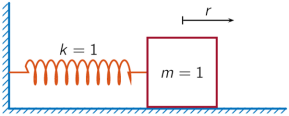

Generate 50 time samples. Define the sampling interval $\Delta t=1/F_s$.

Fs = 5;
dt = 1/Fs;
N = 50;
t = dt*(0:N-1);

The oscillator can be described by the state-space equations


$$\matrix{x(k+1)=Ax(k)+Bu(k),\cr y(k)=Cx(k)+Du(k),\cr}$$


where $x=\pmatrix{r&v}^T$ is the state vector, $r$ and $v$ are respectively the position and velocity of the mass, and the matrices


$$A=\pmatrix{\cos\Delta t&\sin\Delta t\cr-\sin\Delta t&\cos\Delta
t\cr},\quad B=\pmatrix{1-\cos\Delta t\cr\sin\Delta t\cr},\quad
C=\pmatrix{-1&0\cr},\quad D=\pmatrix{1\cr}.$$


A = [cos(dt) sin(dt);-sin(dt) cos(dt)];
B = [1-cos(dt);sin(dt)];
C = [-1 0];
D = 1;

The system is excited with a unit impulse in the positive direction. Use the state-space model to compute the time evolution of the system starting from an all-zero initial state.

u = [1 zeros(1,N-1)];

x = [0;0];
for k = 1:N
    y(k) = C*x + D*u(k);
    x = A*x + B*u(k);
end

Plot the acceleration of the mass as a function of time.

stem(t,y,'filled')
xlabel('t')

Compute the time-dependent acceleration using the transfer function *H*(*z*) to filter the input. Plot the result.

[b,a] = ss2tf(A,B,C,D);
yt = filter(b,a,u);

stem(t,yt,'filled')
xlabel('t')

The transfer function of the system has an analytic expression:


$$H(z)={{1-z^{-1}(1+\cos\Delta t)+z^{-2}\cos\Delta 
t}\over{1-2z^{-1}\cos\Delta t+z^{-2}}}.$$


Use the expression to filter the input. Plot the response.

bf = [1 -(1+cos(dt)) cos(dt)];
af = [1 -2*cos(dt) 1];
yf = filter(bf,af,u);

stem(t,yf,'filled')
xlabel('t')

The result is the same in all three cases.

*Copyright 2021 The MathWorks, Inc.*